# **3EC401ME24 Image Processing**

## Tutorial - 2      Date: 09/08/2023    Roll No :- 22bec121

### 1. Write a MATLAB code to visualize a negative of any grayscale image without using inbuilt function.

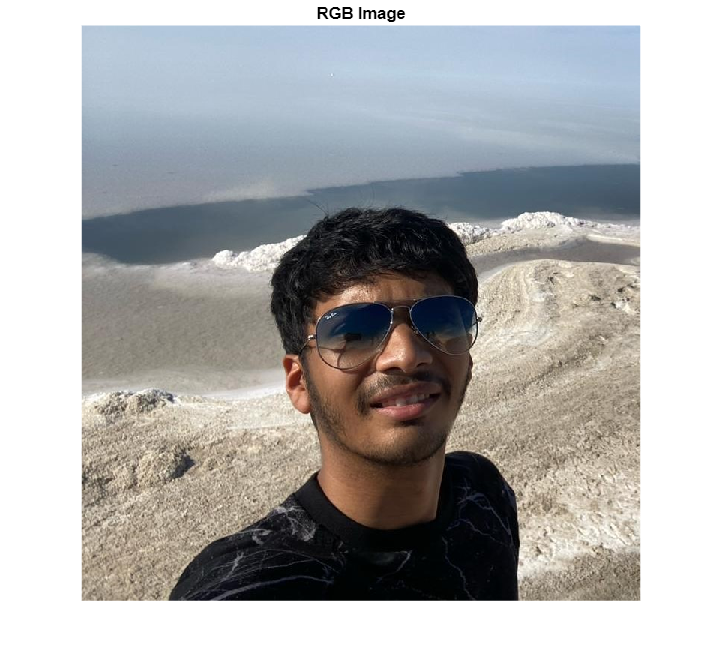

clc ; clear all ; close all ;
img = imread("C:\Users\snehs\Downloads\WhatsApp Image 2024-04-11 at 4.26.29 PM.jpeg");
imshow(img); title("RGB Image");

**Inference :- **Here , we learnt to read an image file from the PC and display it in Matlab .

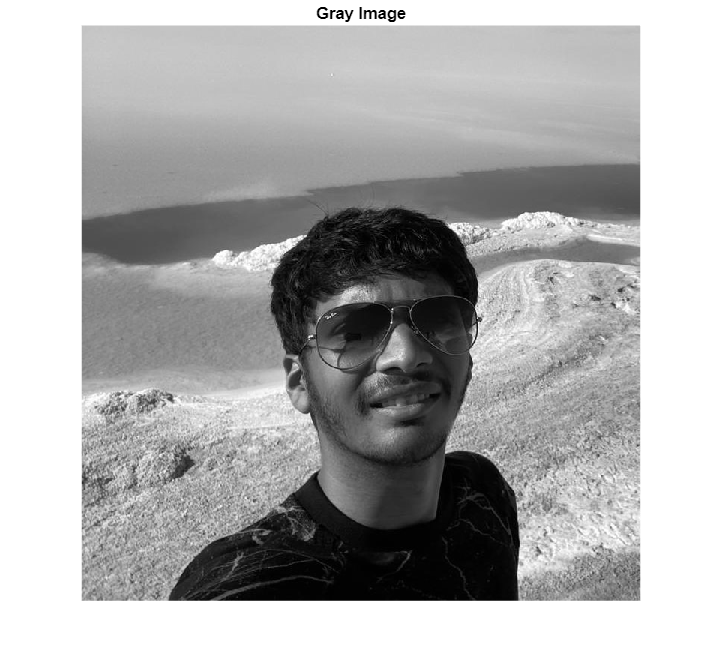

grayimg = im2gray(img);
imshow(grayimg); title("Gray Image"); 

**Inference :- **Here , we learnt to convert an rgb image to gray image for further analysis .

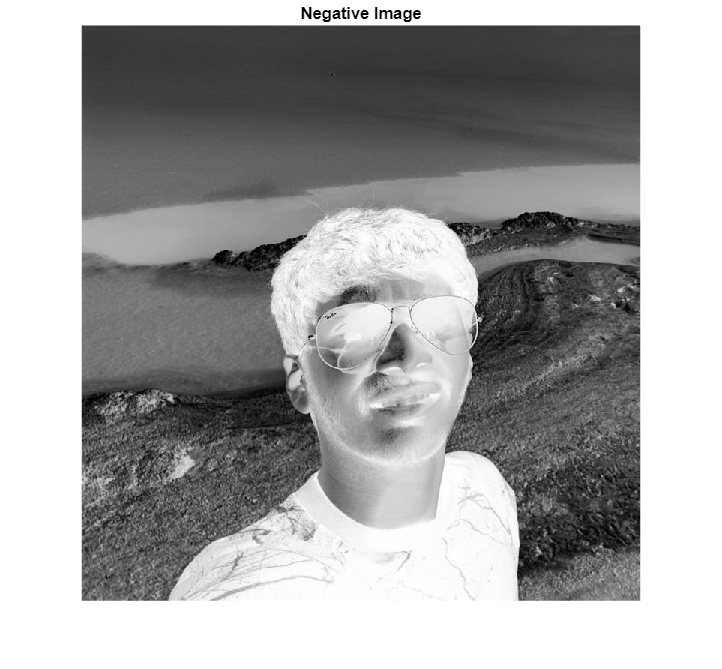

negimg = 255 - grayimg ;
imshow(negimg); title("Negative Image");

**Inference :- **Here , we learnt to convert a gray image to its negative image by subtrating 255 from all the bits.

### 2. Write a MATLAB code to adjust brightness and contrast of given grayscale image using arithmetic operations. Comment upon the values that lead to a better contrast or brightness of an image.

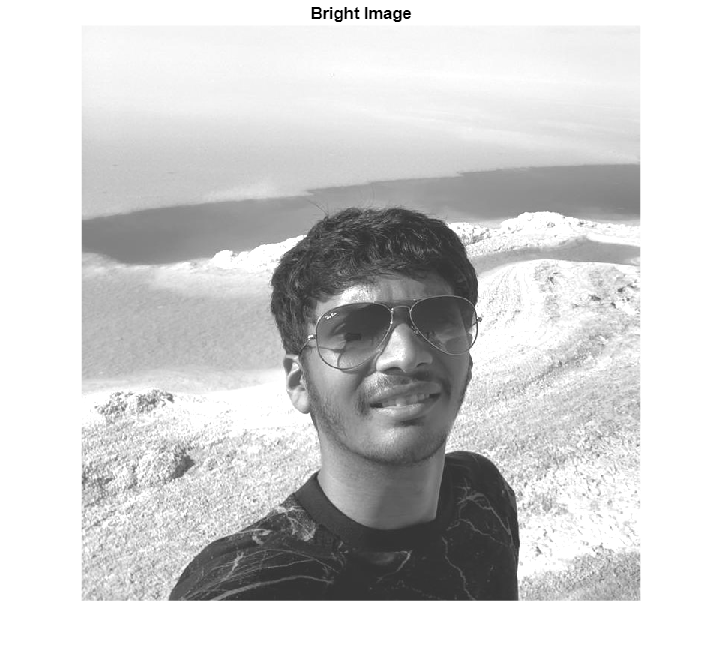

%Brightness
brightimg = 50 + grayimg ;
imshow(brightimg); title("Bright Image");

**Inference :- **Here , we learnt to brighten the image by adding 50 to each of the pixels .

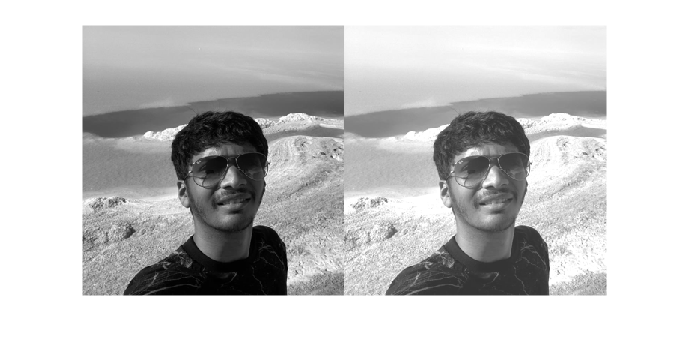

montage({grayimg , brightimg});

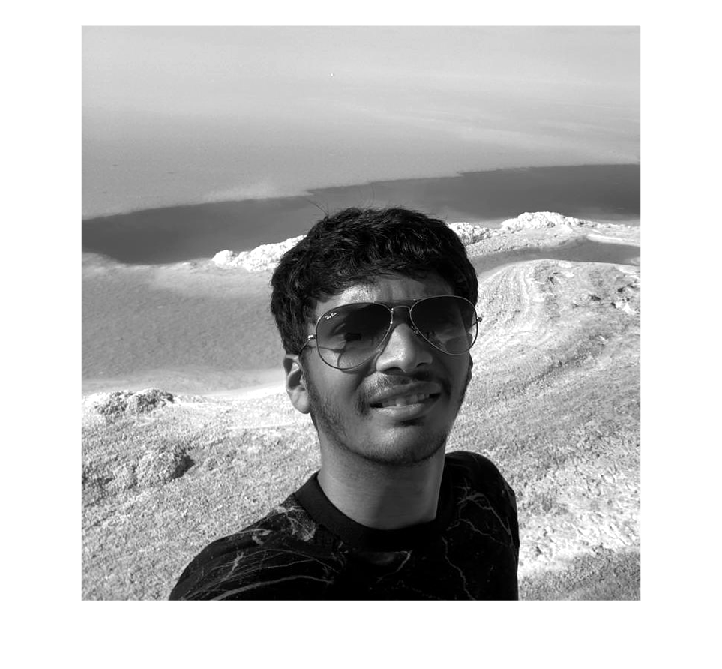

%Contrast
contrastimg = imadjust(grayimg);
imshow(contrastimg);

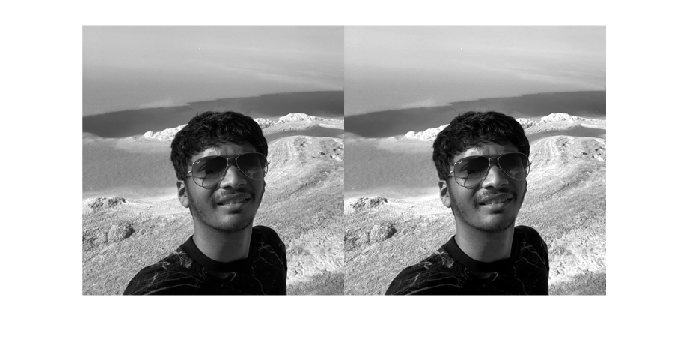

montage({grayimg , contrastimg});

**Inference :- **Here , we changed the contrast of the image by using imadjust function and comaring them .

%Without inbuilt functions 
[l b] = size(grayimg) ;
disp(l); disp(b);

   767

   745



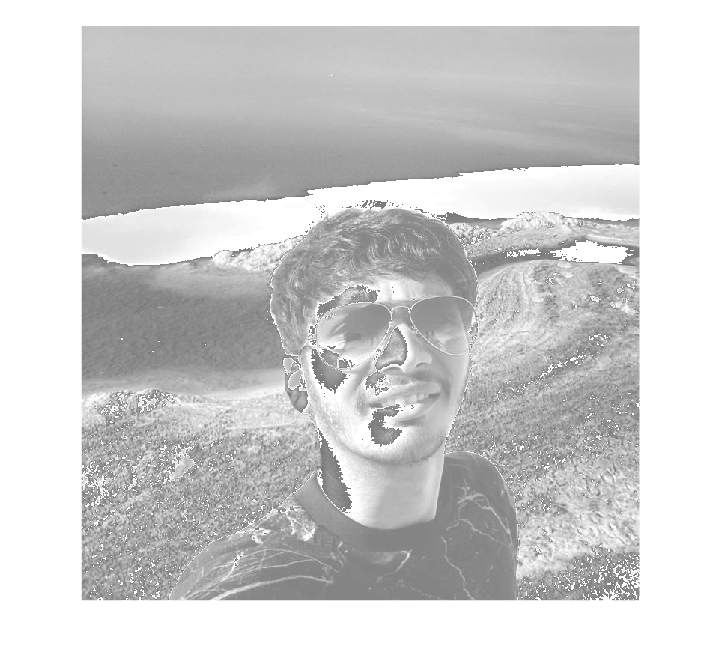

for i = 1:l 
    for j = 1:b
        if (grayimg(i,j) <= 120)
            newimg(i,j) = 1.2 * grayimg(i,j) +130 ;
        else if (120 < grayimg(i,j) < 200)   
            newimg(i,j) = grayimg(i,j) ;
        else
            newimg(i,j) = 1.5 * grayimg(i,j) + 100 ;
        end
        end
    end
end
imshow(newimg);

**Inference :- **Here , we learnt to change brightness and contrast of an image without using in-built function and use only for loops to do it.

### 3. Write a MATLAB code to perform following operations: 

###         a. Log transformation 

###         b. Power law (Gamma) transformation 

###         c. Gamma correction 

### After completion, comment upon the choice of transformation required for given image.

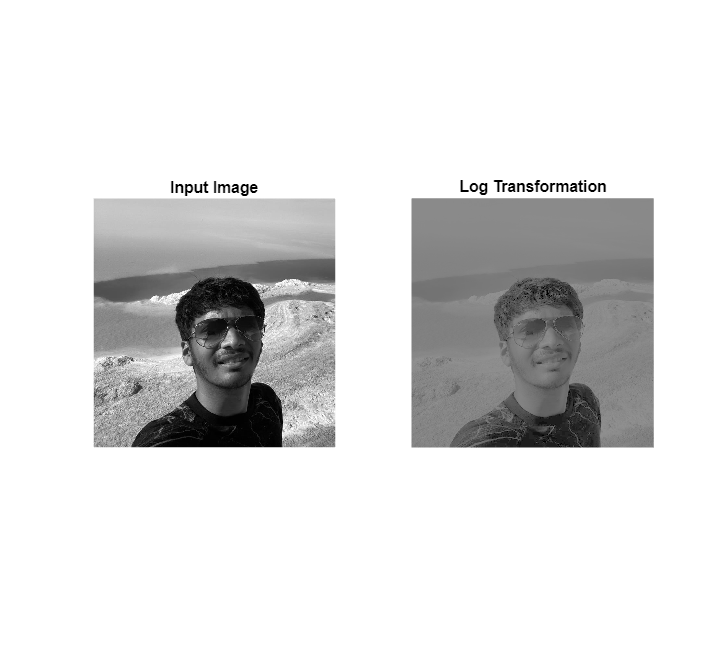

% Log Transformation

grayimg1 = double(grayimg) ;
m = max(max(grayimg1)) ;

C = 255/(log10(1 + m));
S = 60 * log10(1 + grayimg1);

B = uint8(S);
subplot(1,2,1) ; imshow(grayimg); title("Input Image") ;
subplot(1,2,2) ; imshow(B) ; title('Log Transformation');

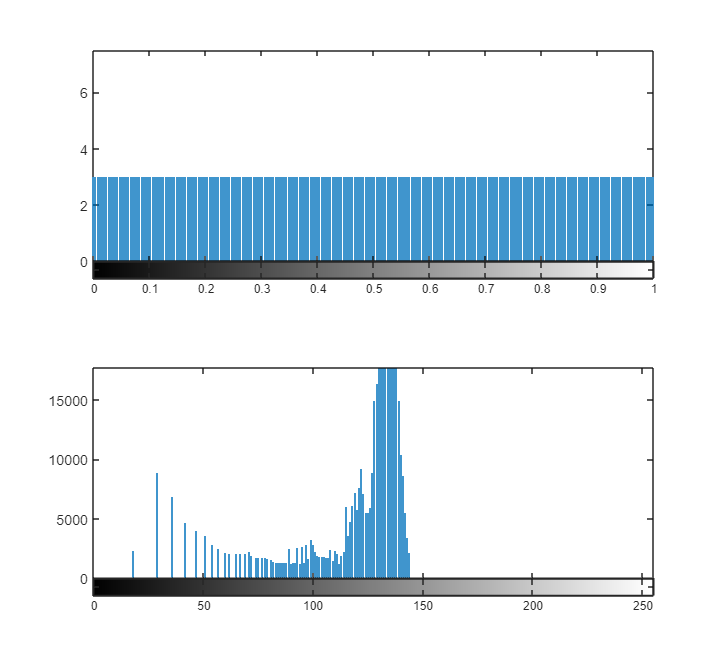

subplot(2,1,1) ; imhist(gray);
subplot(2,1,2) ; imhist(B) ;

**Inference :- **Here , we applied Log Transformation on the image , we can clearly see that the lines present on the tshirt were not visible whereas after applying this transform we can easily be able to see them.

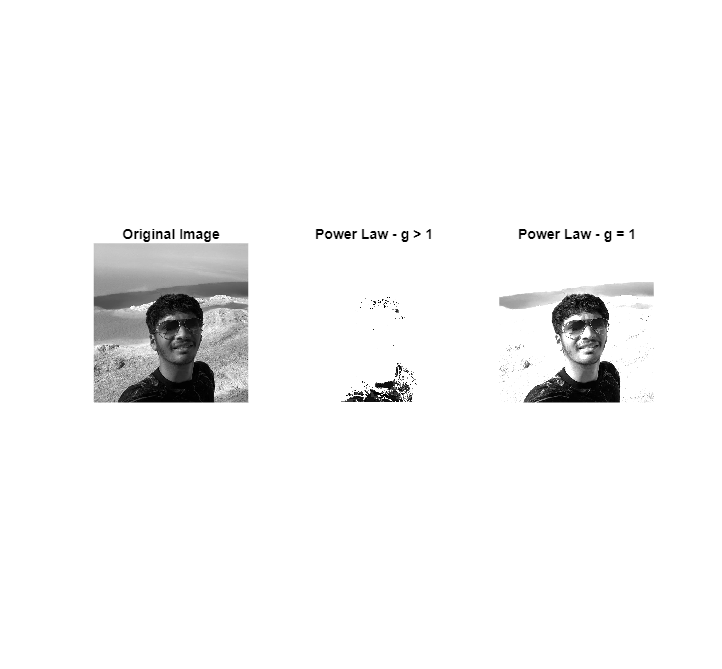

% Power Law Transformation

P1 = 2 * (grayimg .^ 3) ;
P2 = 2 * (grayimg .^ 1) ;

subplot(1,3,1);imshow(grayimg);title("Original Image");
subplot(1,3,2);imshow(P1);title("Power Law - g > 1");
subplot(1,3,3);imshow(P2);title("Power Law - g = 1");

**Inference :- **Here , we applied Power Law transformation on the gray image and observed for different values of contants . We can see that it increase the power of the image .

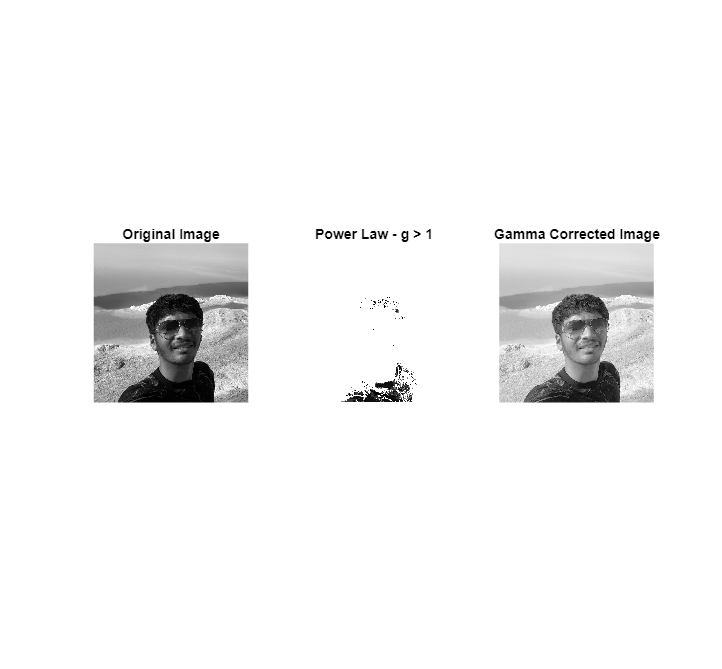

%Gamma Correction

gamma_value = 0.5 ; %We can also check gamma>1
corrected_img = imadjust(grayimg, [], [], gamma_value);
imshow(corrected_img);
title("Gamma Corrected Image");

**Inference :- **Here , we applied Gamma Transformation on the gray image and observed that the Gamma Corrected Image consists of much more details than the original gray image .

### 4. Write a program to stretch contrast of an image with following methods:

###         a. Thresholding

###         b. Intensity level slicing

###         c. Clipping/windowing

### Visualize all results in single window and comment on the processed

### images.

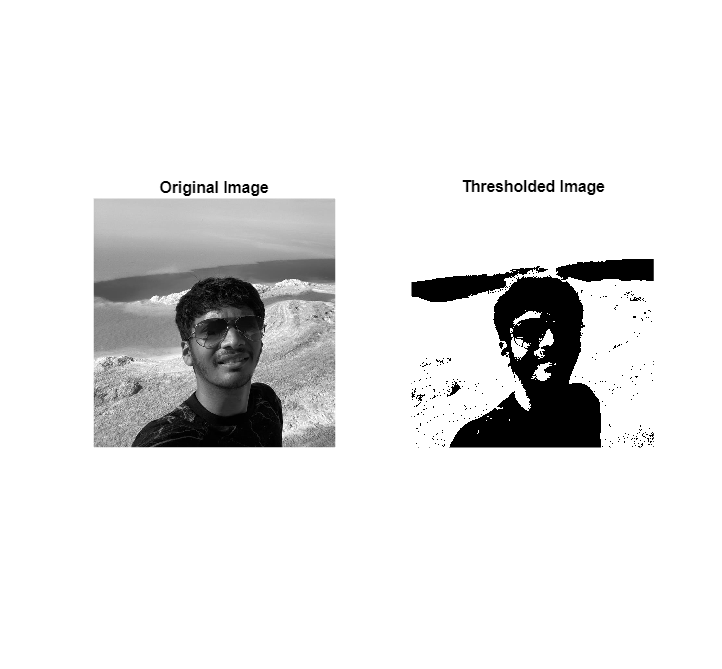

%Thresholding
gray2 = rgb2gray(img);
[m, n] = size(gray2);
t2 = zeros(m, n);
gt = graythresh(gray2);
gray2 = im2double(gray2);

for i = 1:m
    for j = 1:n
        if gray2(i, j) < gt
            t2(i, j) = 0;
        else
            t2(i, j) = 1;
        end
    end
end

subplot(1, 2, 1);
imshow(gray2);
title("Original Image");subplot(1, 2, 2);imshow(t2);title("Thresholded Image");

**Inference :-  **Here , we see thatThresholding simplifies an image into binary form, enhancing contrast but potentially losing detail and being sensitive to lighting conditions.

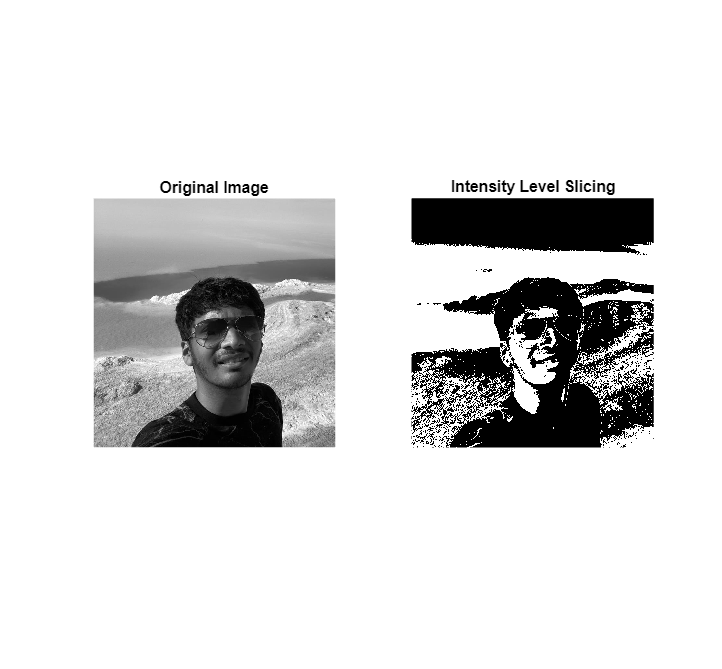

% Intensity level slicing

gray3 = rgb2gray(img) ;

for i = 1 : m
    for j = 1 : n
        if gray3(i,j) > 70 && gray3(i,j) < 170
            out(i,j) = 120 ;
        else
            out(i,j) = 0 ;
        end
    end
end
subplot(1,2,1) ; imshow(grayimg) ; title("Original Image");
subplot(1,2,2) ; imshow(out) ; title("Intensity Level Slicing");

**Inference :- **Here , we can see that Intensity level slicing isolates and highlights specific ranges of pixel intensities, enhancing certain features but possibly ignoring others outside the specified range.

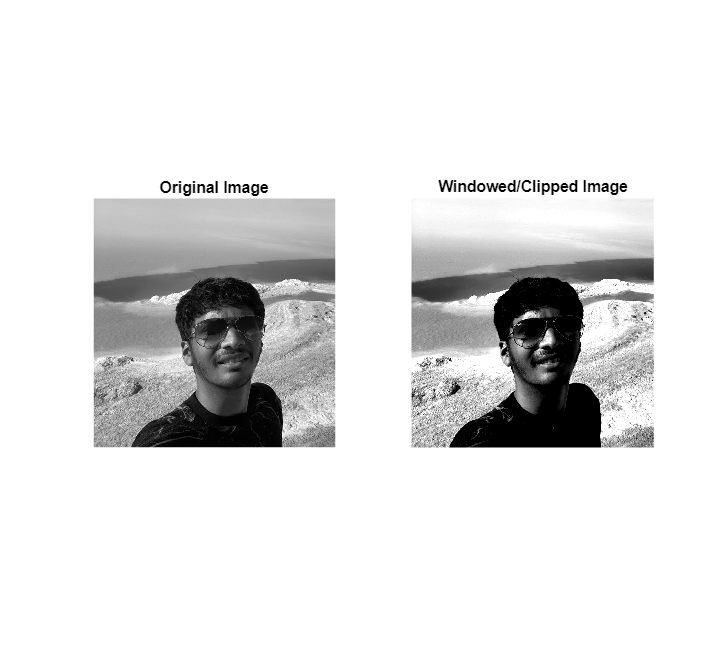

%Clipping/windowing

window_min = 50;
window_max = 200;
clipped_img = grayimg;
clipped_img(clipped_img < window_min) = window_min;
clipped_img(clipped_img > window_max) = window_max;
imshow(clipped_img, []);
title("Windowed/Clipped Image");

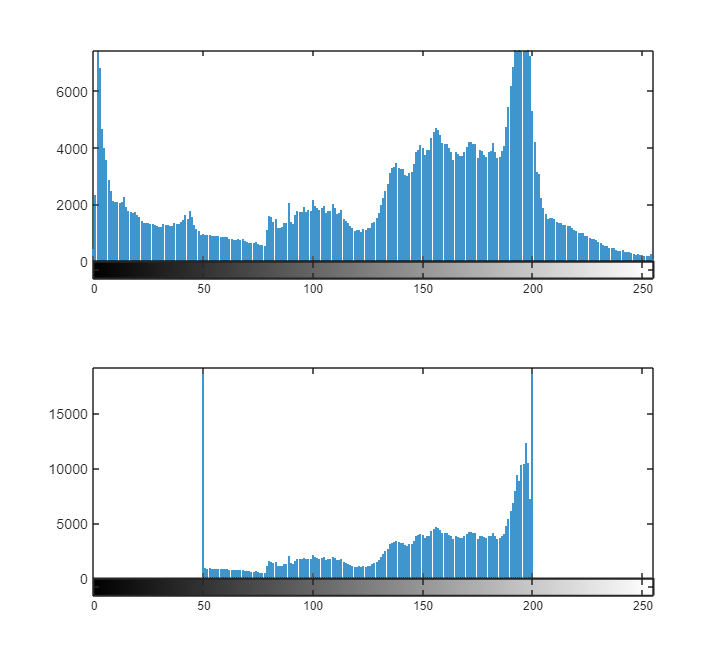

subplot(2,1,1) ; imhist(grayimg);
subplot(2,1,2) ; imhist(clipped_img) ;

**Inference :- **Here , we can clearly see that after Windowing the output image Histogram is rescticted between 50 and 200 intensity levels .

### 5. Write a MATLAB code to extract 8-bit planes from an image.

### Reconstruct the image back using 8th, 7th, 6th and 5th plane. Find the

### difference between original image and reconstructed image.

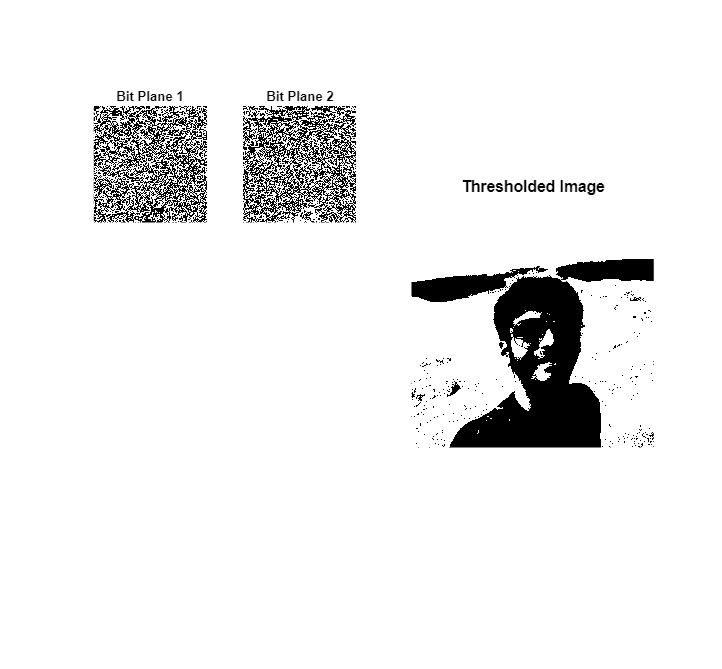

%Bit-Plane Slicing

b1 = zeros(m, n);
b2 = zeros(m, n);
b3 = zeros(m, n);
b4 = zeros(m, n);
b5 = zeros(m, n);
b6 = zeros(m, n);
b7 = zeros(m, n);
b8 = zeros(m, n);

for i = 1:m
    for j = 1:n
        b1(i, j) = bitget(grayimg(i, j), 1) ;
        b2(i, j) = bitget(grayimg(i, j), 2) ;
        b3(i, j) = bitget(grayimg(i, j), 3) ;
        b4(i, j) = bitget(grayimg(i, j), 4) ;
        b5(i, j) = bitget(grayimg(i, j), 5) ;
        b6(i, j) = bitget(grayimg(i, j), 6) ;
        b7(i, j) = bitget(grayimg(i, j), 7) ;
        b8(i, j) = bitget(grayimg(i, j), 8) ;
    end
end

subplot(2, 4, 1);
imshow(b1);
title("Bit Plane 1");

subplot(2, 4, 2);
imshow(b2);
title("Bit Plane 2");

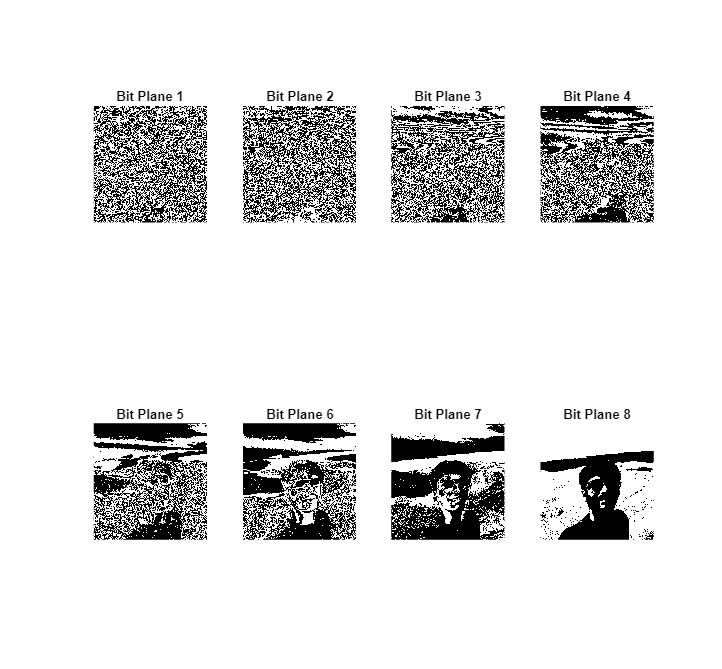


subplot(2, 4, 3);
imshow(b3);
title("Bit Plane 3");

subplot(2, 4, 4);
imshow(b4);
title("Bit Plane 4");

subplot(2, 4, 5);
imshow(b5);
title("Bit Plane 5");

subplot(2, 4, 6);
imshow(b6);
title("Bit Plane 6");

subplot(2, 4, 7);
imshow(b7);
title("Bit Plane 7");

subplot(2, 4, 8);
imshow(b8);
title("Bit Plane 8");

**Inference :- **Here , we split the 8-bit gray image to its respective 8 bit planes and view thm individually .We can see that the bit plane 7 and 8 contains the most of the information .

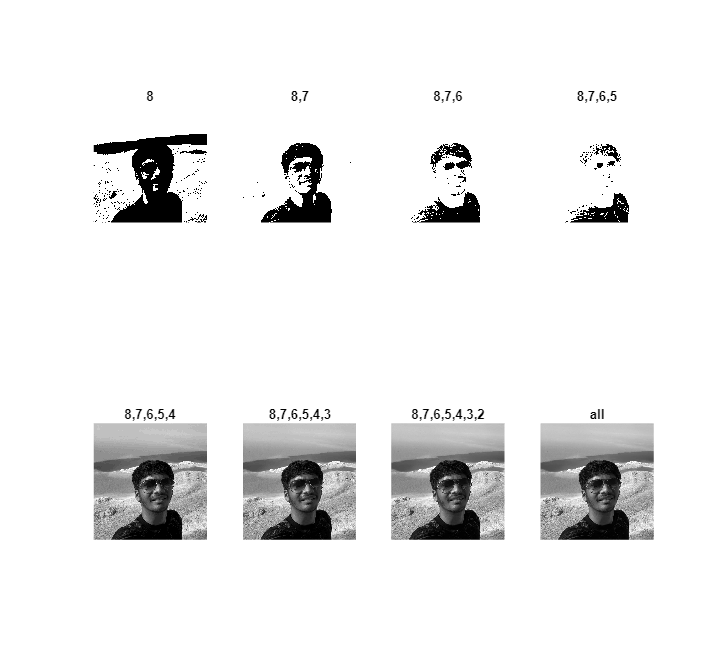

%Reconstruction

out1 = (2^7).*b8;
out2 = (2^7).*b8 + (2^6).*b7;
out3 = (2^7).*b8 + (2^6).*b7 + (2^5).*b6;
out4 = ((2^7).*b8 + (2^6).*b7 + (2^5).*b6 + (2^4).*b5);
out5 = uint8((2^7).*b8 + (2^6).*b7 + (2^5).*b6 + (2^4).*b5 + (2^3).*b4);
out6 = uint8((2^7).*b8 + (2^6).*b7 + (2^5).*b6 + (2^4).*b5 + (2^3).*b4 + (2^2).*b3);
out7 = uint8((2^7)*b8 + (2^6)*b7 + (2^5)*b6 + (2^4)*b5 + (2^3)*b4 + (2^2)*b3 + (2^1)*b2);
out8 = uint8((2^7).*b8 + (2^6).*b7 + (2^5).*b6 + (2^4).*b5 + (2^3).*b4 + (2^2).*b3 + (2^1).*b2 + (2^0).*b1);
subplot(2,4,1) ; imshow(out1) ; title("8");
subplot(2,4,2) ; imshow(out2) ; title("8,7");
subplot(2,4,3) ; imshow(out3) ; title("8,7,6");
subplot(2,4,4) ; imshow(out4) ; title("8,7,6,5");
subplot(2,4,5) ; imshow(out5) ; title("8,7,6,5,4");
subplot(2,4,6) ; imshow(out6) ; title("8,7,6,5,4,3");
subplot(2,4,7) ; imshow(out7) ; title("8,7,6,5,4,3,2");
subplot(2,4,8) ; imshow(out8) ; title("all");

**Inference :- **Here , we reconstructed the images by adding the planes , we can clearly see that planes 8,7,6,5,4 almost resembles the original image . This is one of the techniques used to reduce the size of the image in day- to - day life .


%%%%%%%%%%%%% MEAN SQUARE ERROR %%%%%%%%

g = im2double(grayimg);
out4 = im2double(out4);
out5 = im2double(out5);
out6 = im2double(out6);
out7 = im2double(out7);
out8 = im2double(out8);
e1 = immse(out1,g)

e1 = 1.0633e+04

e2 = immse(out2,g)

e2 = 1.6050e+04

e3 = immse(out3,g)

e3 = 1.9030e+04

e4 = immse(out4,g)

e4 = 2.0707e+04

e5 = immse(out5,g)

e5 = 2.6694e-04

e6 = immse(out6,g)

e6 = 5.3801e-05

e7 = immse(out7,g)

e7 = 7.6824e-06

e8 = immse(out8,g)

e8 = 0

e1snrdb = 20*log(e1)

e1snrdb = 185.4336

e2snrdb = 20*log(e2)

e2snrdb = 193.6690

e3snrdb = 20*log(e3)

e3snrdb = 197.0756

e4snrdb = 20*log(e4)

e4snrdb = 198.7642

e5snrdb = 20*log(e5)

e5snrdb = -164.5698

e6snrdb = 20*log(e6)

e6snrdb = -196.6043

e7snrdb = 20*log(e7)

e7snrdb = -235.5315

e8snrdb = 20*log(e8)

e8snrdb = -Inf

ssim1 = ssim(out1,g)

ssim1 = 0.0235

ssim2 = ssim(out2,g)

ssim2 = 0.0226

ssim3 = ssim(out3,g)

ssim3 = 0.0196

ssim4 = ssim(out4,g)

ssim4 = 0.0159

ssim5 = ssim(out5,g)

ssim5 = 0.9431

ssim6 = ssim(out6,g)

ssim6 = 0.9805

ssim7 = ssim(out7,g)

ssim7 = 0.9973

ssim8 = ssim(out8,g)

ssim8 = 1

### 6. Write a program to plot histogram of an input image. Equalize the histogram and visualise the results.

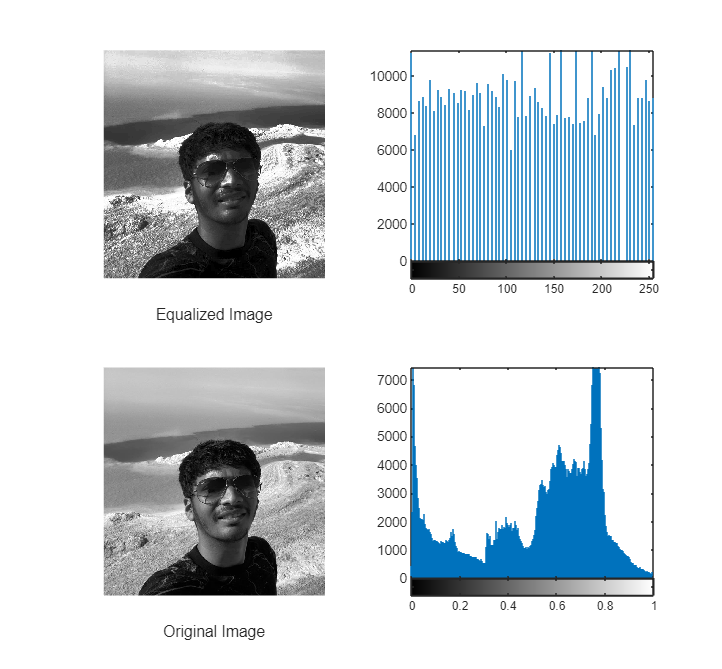

eq = histeq(grayimg);
subplot(2,2,1) ; imshow(eq) ; xlabel('Equalized Image');

subplot(2,2,2) ; imhist(eq); 
subplot(2,2,3) ; imshow(g) ; xlabel('Original Image');
subplot(2,2,4) ; imhist(g);

**Inference :- **Here , we can clearly see in teh Equalized Image Histogram that the histogram is spreaded evenly accross all the various intensity levels .

### Conclusion 

        In this exeriment , we learnt different image processing techniques for manipulating and enhancing grayscale images, including negative transformation, brightness and contrast adjustment, various types of image transformations (logarithmic, power law, gamma correction), and contrast stretching. By applying these methods, one can effectively improve image visibility, highlight features, and adjust visual qualities to suit specific applications.